## Zadanie 7.1


value = 0.323456;
sign=1; %0-unsigned value, 1-signed value % sign
prec_i=1; %number of integer part bits (Nc) % one bit
prec_f=8; %number of fractional part bits (Nu) % eight bits
word = 1 + prec_i + prec_f; % whole word
o_fix = fi(value,sign,word,prec_f)

o_fix =     0.3242

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 10
        FractionLength: 8

A = 0.32345;
B = -0.78743;
C = 0.56532;

A_fix = fi(A, 1, 8, 6);
epsA = A - double(A_fix)

epsA = -0.0047


B_fix = fi(B, 1, 8, 6);
epsB = B - double(B_fix)

epsB = -0.0062


C_fix = fi(C, 1, 8, 6);
epsC = C - double(C_fix)

epsC = 0.0028

Y = (A + B) * C;
Y_fix = (A_fix + B_fix) * C_fix;

epsY = Y - double(Y_fix);


res = zeros(1,17);
for prec_f=0:16
    A_fix = fi(A, 1, prec_f+2, prec_f);
    B_fix = fi(B, 1, prec_f+2, prec_f);    
    C_fix = fi(C, 1, prec_f+2, prec_f);
    prec_f
    
    Y_fix = (A_fix + B_fix) * C_fix
    bin(Y_fix)
    res(prec_f+1) = abs(Y - double(Y_fix));
    double(res(prec_f+1))
end

prec_f = 0

Y_fix =     -1

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 5
        FractionLength: 0

ans = '11111'

ans = 0.7377

prec_f = 1

Y_fix =    -0.2500

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 7
        FractionLength: 2

ans = '1111111'

ans = 0.0123

prec_f = 2

Y_fix =    -0.2500

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 9
        FractionLength: 4

ans = '111111100'

ans = 0.0123

prec_f = 3

Y_fix =    -0.2344

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 11
        FractionLength: 6

ans = '11111110001'

ans = 0.0279

prec_f = 4

Y_fix =    -0.2813

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 13
        FractionLength: 8

ans = '1111110111000'

ans = 0.0190

prec_f = 5

Y_fix =    -0.2637

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 15
        FractionLength: 10

ans = '111111011110010'

ans = 0.0014

prec_f = 6

Y_fix =    -0.2549

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 17
        FractionLength: 12

ans = '11111101111101100'

ans = 0.0074

prec_f = 7

Y_fix =    -0.2637

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 19
        FractionLength: 14

ans = '1111110111100100000'

ans = 0.0014

prec_f = 8

Y_fix =    -0.2633

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 21
        FractionLength: 16

ans = '111111011110010011001'

ans = 9.9323e-04

prec_f = 9

Y_fix =    -0.2613

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 23
        FractionLength: 18

ans = '11111101111010001110011'

ans = 0.0010

prec_f = 10

Y_fix =    -0.2623

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 25
        FractionLength: 20

ans = '1111110111100110110101111'

ans = 1.2895e-05

prec_f = 11

Y_fix =    -0.2626

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 27
        FractionLength: 22

ans = '111111011110011001000110110'

ans = 2.6319e-04

prec_f = 12

Y_fix =    -0.2623

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 29
        FractionLength: 24

ans = '11111101111001101101011110000'

ans = 1.2895e-05

prec_f = 13

Y_fix =    -0.2623

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 31
        FractionLength: 26

ans = '1111110111100110110100010000001'

ans = 5.1187e-07

prec_f = 14

Y_fix =    -0.2623

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 33
        FractionLength: 28

ans = '111111011110011011010001000000100'

ans = 5.1187e-07

prec_f = 15

Y_fix =    -0.2623

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 35
        FractionLength: 30

ans = '11111101111001101101000100000010000'

ans = 5.1187e-07

prec_f = 16

Y_fix =    -0.2623

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 37
        FractionLength: 32

ans = '1111110111100110110100011101000110001'

ans = 2.0581e-06

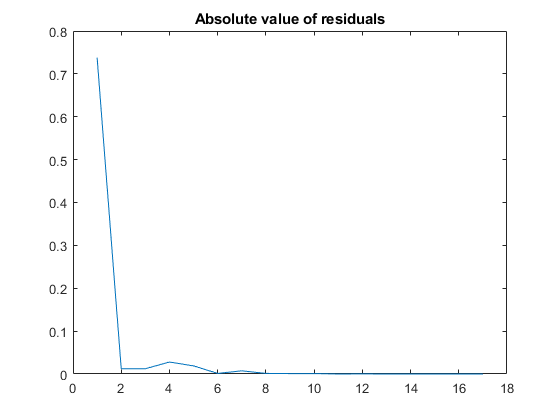

plot(res)
title("Absolute value of residuals")

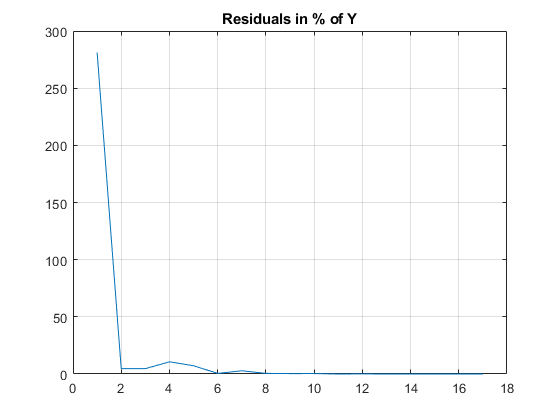

plot(abs(res/Y_fix)*100)
title("Residuals in % of Y")
grid on

prec_f = 8;
A_fix = fi(A, 1, prec_f+2, prec_f);
B_fix = fi(B, 1, prec_f+2, prec_f);    
C_fix = fi(C, 1, prec_f+2, prec_f);
prec_f

prec_f = 8


Y_fix = (A_fix + B_fix) * C_fix

Y_fix =    -0.2633

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 21
        FractionLength: 16

bin(Y_fix)

ans = '111111011110010011001'

a = bin(A_fix)

a = '0001010011'

b = bin(B_fix)

b = '1100110110'

c = bin(C_fix)

c = '0010010001'

## Zadanie 7.2

A = -100.3436

A = -100.3436

B = 7.367

B = 7.3670

C = -4.92

C = -4.9200

D = 9.111

D = 9.1110

E = -99.99

E = -99.9900

F = 134.56

F = 134.5600

A_fix = fi(A, 1, 1+9+8, 8)

A_fix =  -100.3438

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 18
        FractionLength: 8

B_fix = fi(B, 1, 1+4+3, 3)

B_fix =     7.3750

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 8
        FractionLength: 3

C_fix = fi(C, 1, 1+4+7, 7)

C_fix =    -4.9219

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 12
        FractionLength: 7

D_fix = fi(D, 1, 1+5+2, 2)

D_fix =      9

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 8
        FractionLength: 2

E_fix = fi(E, 1, 1+8+5, 5)

E_fix =   -100

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 14
        FractionLength: 5

F_fix = fi(F, 1, 1+9+9, 9)

F_fix =   134.5605

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 19
        FractionLength: 9

a = bin(A_fix)

a = '111001101110101000'

b = bin(B_fix)

b = '00111011'

c = bin(C_fix)

c = '110110001010'

d = bin(D_fix)

d = '00100100'

e = bin(E_fix)

e = '11001110000000'

f = bin(F_fix)

f = '0010000110100011111'

input = {a; b; c; d; e; f}

input = 6×1 cell array
    {'111001101110101000' }
    {'00111011'           }
    {'110110001010'       }
    {'00100100'           }
    {'11001110000000'     }
    {'0010000110100011111'}


test_output = ((A_fix + B_fix) * C_fix) + ((D_fix + E_fix) * (E_fix + F_fix))

test_output =   -2.6874e+03

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 37
        FractionLength: 15

test_output_bin = bin(test_output)

test_output_bin = '1111111111010110000000100100100010000'

## Zadanie 7.3

A = 21.37;
A_fix = fi(A, 1, 1+8+4, 4)

A_fix =    21.3750

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 13
        FractionLength: 4

a = bin(A_fix)

a = '0000101010110'

Y_fix = fi(0, 1, 8+1+8+4, 4)

Y_fix =      0

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 21
        FractionLength: 4

for i = 1:10
    Y_fix = accumpos(Y_fix, A_fix)
end

Y_fix =    21.3750

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 21
        FractionLength: 4

Y_fix =    42.7500

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 21
        FractionLength: 4

Y_fix =    64.1250

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 21
        FractionLength: 4

Y_fix =    85.5000

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 21
        FractionLength: 4

Y_fix =   106.8750

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 21
        FractionLength: 4

Y_fix =   128.2500

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 21
        FractionLength: 4

Y_fix =   149.6250

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 21
        FractionLength: 4

Y_fix =    171

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 21
        FractionLength: 4

Y_fix =   192.3750

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 21
        FractionLength: 4

Y_fix =   213.7500

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 21
        FractionLength: 4

y = hex(Y_fix)

y = '000d5c'

## Zadanie 7.4

m11 = fi(-0.11, 1, 1+8+4, 4)

m11 =    -0.1250

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 13
        FractionLength: 4

m12 = fi(2.3, 1, 1+8+4, 4)

m12 =     2.3125

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 13
        FractionLength: 4

m21 = fi(3.14, 1, 1+8+4, 4)

m21 =     3.1250

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 13
        FractionLength: 4

m22 = fi(-11.25, 1, 1+8+4, 4)

m22 =   -11.2500

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 13
        FractionLength: 4

matrix_input = {m11; m12; m21; m22}

matrix_input = 4×1 cell array
    {1×1 embedded.fi}
    {1×1 embedded.fi}
    {1×1 embedded.fi}
    {1×1 embedded.fi}


M = [m11, m12; m21, m22]

M =    -0.1250    2.3125
    3.1250  -11.2500

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 13
        FractionLength: 4

A = fi(0.13, 1, 1+8+4, 4)

A =     0.1250

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 13
        FractionLength: 4

a = bin(A)

a = '0000000000010'

B = fi(2.25, 1, 1+8+4, 4)

B =     2.2500

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 13
        FractionLength: 4

b = bin(B)

b = '0000000100100'

prod_A_11 = A * m11

prod_A_11 =    -0.0156

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 26
        FractionLength: 8

prod_A_12 = A * m21

prod_A_12 =     0.3906

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 26
        FractionLength: 8

prod_B_21 = B * m12

prod_B_21 =     5.2031

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 26
        FractionLength: 8

prod_B_22 = B * m22

prod_B_22 =   -25.3125

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 26
        FractionLength: 8


X_ = double(prod_A_11+prod_B_21)

X_ = 5.1875

Y_ = double(prod_A_12+prod_B_22)

Y_ = -24.9219

res = M * [A; B]

res =     5.1875
  -24.9219

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 27
        FractionLength: 8

res_bin = bin(res)

res_bin = 2×27 char array
    '000000000000000010100110000'
    '111111111111110011100010100'


res_hex = hex(res)

res_hex = 2×7 char array
    '0000530'
    '7ffe714'


## Test zamiany na fixed step

% A = 0.3892
% res = zeros(1,17);
% for prec_f=0:16
%     A_fix = fi(A, 1, prec_f+2, prec_f)
%     A_bin = bin(A_fix)
%     res(prec_f+1) = abs(A - double(A_fix));
%     double(res(prec_f+1))
% end